## Sistemas Realimentados

## EP - Exemplo de exercício proposto e sua solução

## **Nome de quem fez o exercício: Nome1 e Nome 2**

**1) Sugira um modelo de ordem 1 tal que seu tempo de estabelecimento seja de 8s e a saída seja igual à entrada em regime. Explique como obteve os parâmetros do modelo e simule sua resposta confirmando as características desejadas.**

*Solução:*

De acordo com as notas de aula, a resposta de um sistema de primeira ordem dado por $G(s)=\frac{1}{Ts+1}$ e a mostrada na figura abaixo.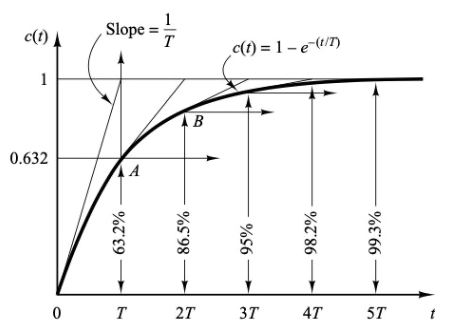

A constante de tempo T é o tempo necessário para a saída atingir 63.2% do valor de regime. O tempo de estabelecimento, considerando uma saída em 98.2% do valor do regime é igual a 4T. Portanto, para um tempo de estabelecimento de 8 segundos tem-se $T=2$.

O valor em regime para entrada degrau é obtido usando o teorema do valor final, ou seja, lim $y(t)$ quando $t\rightarrow \infty$ é dado por lim quando  $s\rightarrow 0$ de $Y(s)=sG(s)U(s)=sG(s)\frac{1}{s}=s\frac{1}{s(s+1)} = 1$.

Caso o numerador de $G(s)$ seja $K$, o valor de regime será$K$.

Portanto, $G(s)=\frac{1}{2s+1}$ fornece a resposta desejada.

Agora a confirmação via simulação:

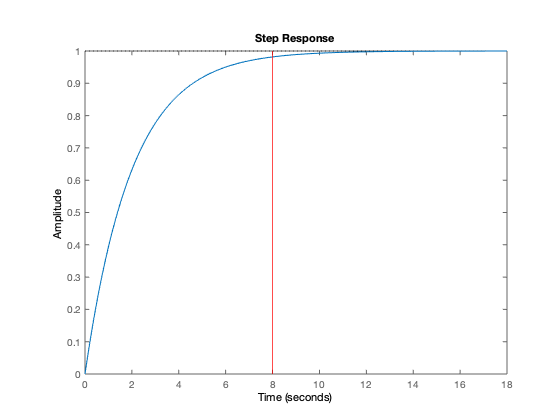

g=tf(1,[2 1]);
figure;
step(g);
xline(8,'r');

**2) Sugira um modelo de ordem 2 tal que sua sobreelevação seja de 10% e o tempo de estabelecimento seja 100s.**

**Explique como obteve os parâmetros do modelo e simule sua resposta confirmando as características desejadas.**

*Solução:*

A relação entre sobre-elevação e amortecimento é dada por $\mathrm{UP}=100e^{-\zeta \pi /\sqrt{1-\zeta^2 }}$.

Calculando $\zeta$ a partir de $UP$:

UP=10;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2))

zeta = 0.5912

O tempo de estabelecimento ts pode ser aproximado por $ts=\frac{4}{\zeta\omega_n}$.

Portanto, pode-se obter $\omega_n=\frac{4}{\zeta ts}$, e tem-se

ts=100;
wn=4/(zeta*ts)

wn = 0.0677

O modelo que dá a resposta desejada é $G(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$

g1=tf(wn^2,[1 2*zeta*wn wn^2])


g1 =
 
         0.004578
  -----------------------
  s^2 + 0.08 s + 0.004578
 
Continuous-time transfer function.



A resposta ao degrau deste modelo é:

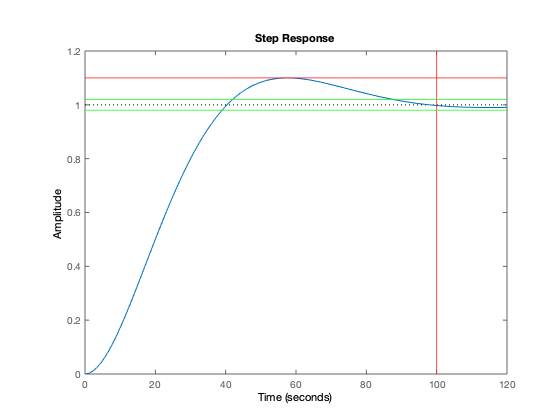

figure;
step(g1);
xline(100,'r');
yline(1.10,'r');
yline(1.02,'g');
yline(0.98,'g');